# Generating Surface Meshes and Calculating Metrics for a subset of dying cells

## Overview

This script generates cell surface meshes for a set of taste cells that are dying but that have not had their lysosomes segmented. The metrics calculated from these cells will be used for cell size analysis

Since these cells do not have their lysosomes, we did not add their information to the main idT table or their traces to the main VL table. Instead we created a separate table to organize the cell info and used that table to generate a separate VL table used only in this script.

Refer to the [generate_cellMesh_cellT.mlx](matlab:open('./generate_cellMesh_cellT.mlx')) script for more details on cell mesh generation. 

### REQUIREMENTS: 

- ManifoldPlus [https://github.com/hjwdzh/ManifoldPlus](https://github.com/hjwdzh/ManifoldPlus) 

- pyMeshFix: [https://pymeshfix.pyvista.org](https://pymeshfix.pyvista.org)

- MathWorks Lidar Toolbox

- MatGeom Toolbox (meshVolume function)

### DATA GENERATED

#### Mesh Files

OBJ files: Three different meshes generated for each cell trace and stored as OBJ files in the cell Meshes folder

- CELL_ID_as.obj - mesh created by MATLAB alphaShape function

- CELL_ID_mp.obj - watertight mesh created by ManifoldPlus

- CELL_ID_fx.obj - watertight mesh generated by pyMeshFix

Note: some cell traces that belonged to the same cell were saved with different Object names. For example, TB2_TCdying-01-apical_cw and  TB2_TCdying-01_cw are from the same cell. Meshes created from two different cell objects were saved by their ID name. In this case, TB_TCdying01.

#### MATLAB TABLES

**dyIDT** contains the imported data from the dying_list.csv file

**dyCellMeshT.mat** contains table variable information about the generated meshes. Each row in the table contains the data from one Cell. Columns in the table include

- Cell - CELL ID, unique identifier for a cell

- Type - taste cell type

- Health - early or late dying

- Polarity - apical direction of cell. 1 means keep default direction, -1 means invert

- AlphaRadius - setting used in alphaShape NaN means default value used)

- VolAS - volume of AlphaShape mesh

- VolMP - volume of Manifold Plus mesh

- VolFX - volume pyMeshFix

**dyingT.mat** contains the info on the cell mesh version that provides the best volume calculation (In some cases, the watertight mesh is less representative of the cell that the original AlphaShape mesh). This is manually decided by visual inspection. 

The columns in the dyingT table are as follows:

- Cell: Cell ID

- Type: Taste cell Type, x means unknown

- Health: early or late dying

- Volume, SurfaceArea - the volume and surface area of the manually selected mesh

- SAV: Surface to Volume ratio

- Filename: Name of the cell mesh file used for the volume calculations

NOTE: only run this script after running the [generate_cellMesh_cellT.mlx](matlab:open('./generate_cellMesh_cellT.mlx')) and generating the meshT table there.

## Set-up

clearvars -except paths
close all
clc

### Path to manifoldPlus

Update:

- reconstruct path: contains folder with Reconstruct Data

-  manifoldPlus path for your local installation (../ManifoldPlus/build/manifold)

paths.reconstruct = "/Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/reconstruct data";
paths.manifoldPlus = "/Users/ernesto/github/ManifoldPlus/build/manifold";

## Load Reconstruct Data and generate VL table

### Get Cell Dying ID Table

This table contains the names of a dying cells to be meshed

paths.dyingTableCSV="/Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dying_list.csv";
dyIDT = get_table(paths.dyingTableCSV)

### Set Load Table

Create a loadT table which contains the settings for import

- **load = true** means to process data from the indicated folder

- **load_last = true** means reload the last processed VL (much faster, but doesn't include any new traces)

contents = dir(paths.reconstruct);
contents(~[contents.isdir])=[];

didT = 19×8 table
         Cell                    Object              Type    Health     TB    Dataset        Folder         Mesh
    _______________    __________________________    ____    _______    __    _______    _______________    ____

    "TB2_T2_14"        "TB2_T2cell14_CM_LES"         II      healthy    3      DS2       "ROB_DS2"           0  
    "TB1_AP68"         "TB1_AP68_EM"                 III     early      1      TF21      "ROB_TF21_TB1"      0  
    "TB1_AP43"         "TB1_AP43_EM"                 II      early      1      TF21      "ROB_TF21_TB1"      0  
    "TB1_T2C05"        "TB1_T2cell05_CM_RKJ"         II      early      1      DS2       "ROB_DS2"           0  
    "TB1_T2C06"        "TB1_T2c

contents(contains({contents.name},'.'))=[];
folderNames = string({contents.name}); % get Folder names from reconstruct folder
loadT = table(true(numel(contents),1), ...
    string({contents.name})', ...
    true(numel(contents),1), ...
    VariableNames=["Load" "Folder" "Load_Last"]);
loadT.Load = ismember(folderNames,unique(dyIDT.Folder))'; % is folder name found in didT?

loadT.Load_Last = [true; true; true; false; false] % manually select which folders to load_last

### Get Vertices

dyVL = getAllDyingVL(paths, dyIDT, loadT(loadT.Load,:));

## Generate Dying Cell Meshes

- no lysosomes in this dataset

- resets volume calc in dcmT (if already calculated)

### Generate all

dyCellMeshT = genDyingCellMesh(dyVL,dyIDT, paths); % dying cell meshT
disp(dyCellMeshT)

save(dyCellMeshT.Properties.UserData.filePath,"dyCellMeshT")

loadT = 5×3 table
    Load         Folder         Load_Last
    _____    _______________    _________

    true     "Courtney_TF21"      true   
    true     "ROB_DS2"            true   
    true     "ROB_TF21_TB1"       true   
    false    "Ruibiao_DS2"        false  
    false    "TOM_TF21_tb2"       false  


### Generate a subset

only those selected cells indicated

t = genDyingCellMesh(vl,dyIDT(ola,1:7), paths); % dying cell meshT
disp(t)

1. Courtney_TF21.
loading saved trace and series info...
VL loaded from File
2. ROB_DS2.
loading saved trace and series info...
VL loaded from File
3. ROB_TF21_TB1.
loading saved trace and series info...
VL loaded from File
dVL saved as /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dyingVL.mat


save(dyCellMeshT.Properties.UserData.filePath,"dyCellMeshT")

Unrecognized function or variable 'dyVL'.

### Load dcmT if needed

load(fullfile(paths.cellMesh, "dyCellMeshT.mat"),"-mat","dyCellMeshT")

## Inspect Cell Meshes

Once **generateCellMeshes** is complete, it is critical to inspect all of the meshes, especially those that have radically different volume calculations between the various methods.  

dcmT_row = 4; % row in dcmT

dcmT file found and loaded. Using this table for the analysis.

Error using  .  (line 229)
Unrecognized table variable name 'ID'.

Error in generate_dyingMesh_dyingT>genDyingCellMesh (line 161)
[lia, ~] = ismember(didT.ID, dcmT.Cell);

hvwr = displayCellMeshes(dyCellMeshT.Cell(dcmT_row),paths.cellMesh);

- all Cell Dying Cell Meshes appear to be well represented by the MP method

- Copy the meshes 

### Recalculate Cell Meshes

cellName = dyCellMeshT.Cell(dcmT_row);
polarity = 1;
aRadius = 3; % nan if base input wanted
dcmt = generateSingleCellMesh(vl,dyIDT, dyCellMeshT,paths, cellName, polarity, aRadius);

### Update dcmT as needed

dyCellMeshT(dcmT_row,:) = dcmt;

## Calculate Dying Cell Metrics

### load dcmT if needed

load(fullfile(paths.cellMesh,"dyCellMeshT.mat"),"-mat","dyCellMeshT")

### Calculate Cell Metrics from Cell Meshes

1. TB3_TC02_as.obj - 0


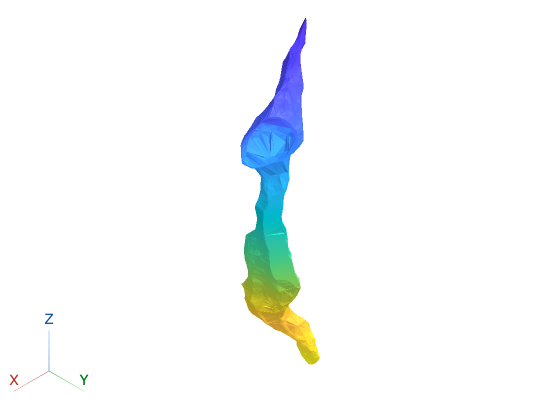

2. TB3_TC02_fx.obj - 0
3. TB3_TC02_mp.obj - 0


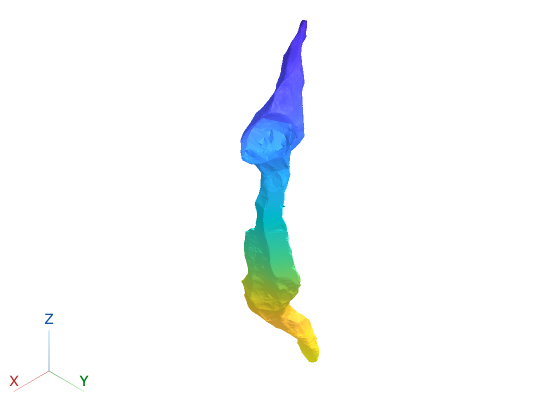

ans =   LinkProp with properties:

          Enabled: 'on'
    PropertyNames: {'CameraPosition'  'CameraZoom'}
          Targets: [1×3 Viewer3D]


dyingT = calcCellMetrics(dyCellMeshT);

dyingT.Properties.UserData.filePath = fullfile(paths.lysosome,"dyingT.mat");
dyingT.Properties.UserData.meshPath = paths.cellMesh;

dyingT.Type = categorical(dyingT.Type);

Unable to resolve the name 'dcmT.Cell'.

dyingT.Health = categorical(dyingT.Health);
type = dyingT.Type;
type(dyingT.Health=="early") = 'ed';
type(dyingT.Health=="late") = 'ld';
dyingT.PlotSort = categorical(type,{'IV','III','II','I','ld','ed'},'ordinal',true);

### Exclude TB2 rows from analysis

- They will be captured in the ***cellT*** dataset

la_tb2 = contains(dyCellMeshT.Cell,"TB2");
dyingT(la_tb2,:) = [];

### save dyingT table

save(dyingT.Properties.UserData.filePath,"dyingT")

# Local Functions

## get all vertices

function dyVL = getAllDyingVL(paths, didT, loadT)
%GETALLVL all trace data identified in idT
%   Analysis: Lysosome Analysis
% OUTPUT
%   - VL: vertices list table contains the x,y,z coordinates of the cells
%       and lysosome tracings


arguments
    paths struct % structure containing paths to the relevant folders
    didT table % id table contains manually entered information (either idT or didT)
    loadT table % table containing load last selections
end

dyVL = [];

for n = 1:height(loadT)
    load_last = loadT.Load_Last(n);
    series_path = fullfile(paths.reconstruct,loadT.Folder(n));
    fprintf('%d. %s.\n',n,loadT.Folder(n));

    [seriesT, traceT] = get_series_contents(series_path,load_last); % true input means load mat files instead

    la = didT.Folder == loadT.Folder(n);

    filter_str = didT.Object(la);

    fTL = filter_trace_list(seriesT,traceT, filter_str,true); % true means exact match
    fTL.Properties.Description = 'dying'; % modifies file name to keep projects separate

    % Load vl
    vl = get_verTCs(seriesT,fTL,load_last);

    img_mag = vl.Properties.UserData.img_mag;
    vl(:,["x","y","z"]) = varfun(@(x) x * img_mag,vl,InputVariables=["x","y","z"]); % convert to microns    

    %Concatenate
    dyVL = [dyVL; vl];
end

dyVL.Properties.VariableUnits(3:5) = repmat({'µm'},1,3);
dyVL.Properties.UserData.idT = didT;

dyVL.Properties.UserData.file = fullfile(paths.lysosome, "dyingVL.mat"); % same folder as live script
save(dyVL.Properties.UserData.file,"dyVL")
fprintf('dyVL saved as %s\n',dyVL.Properties.UserData.file)

end

% switch IDT.Properties.Description
%         case 'dying' %didT
%         filter_str = IDT.Object(la);
%         case 'lys' %idT
%         filter_str = [IDT.Cell(la); IDT.Lysosome(la)];
%     end

## get table

function T = get_table(dyingTableCSV)
opts2 = delimitedTextImportOptions("NumVariables", 8, "Encoding", "UTF-8");

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ",";

% Specify column names and types
opts2.VariableNames = ["Cell", "Object", "Type", "Health", "TB", "Dataset", "Folder", "Mesh"];
opts2.VariableTypes = ["string", "string", "categorical", "categorical", "double", "categorical", "string", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Specify variable properties
opts2 = setvaropts(opts2, ["Cell", "Object"], "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, ["Cell", "Object", "Type", "Health"], "EmptyFieldRule", "auto");
opts2 = setvaropts(opts2, "TB", "TrimNonNumeric", true);
% opts2 = setvaropts(opts2, ["TB", "Dataset", "Folder"], "ThousandsSeparator", ",");

% Import the data
T = readtable(dyingTableCSV, opts2);
T.Properties.Description = 'dying';

% Clear temporary variables
end

## Generate Cell Meshes

Also calculates volumes for each mesh

function [dcmT] = genDyingCellMesh(dyIDT,dyVL,paths)
%GET_CELL_METRICS. Calculates the volume of each cell
% INPUT
%       - didT. Cell Object and ID table. Also contains Mesh column. 
%               Set to false if you want to recalculate the volume
% OUTPUTS: dcmT table contains calculated volumes for the meshes

arguments
    dyIDT table % contains Cell Object and ID names. 
    dyVL table % vertices list table
    paths struct % contains project relevant paths
end

% suppress alpha shape warnings
id = 'MATLAB:alphaShape:DupPointsBasicWarnId';
warning('off',id);


% load previous dcmT table
if exist(fullfile(paths.cellMesh,"dcmT.mat"),'file') % start with meshT
    fprintf('dcmT file found and loaded. Using this table for the analysis.')
    load(fullfile(paths.cellMesh,"dcmT.mat"),"-mat","dcmT") % load dcmT
    % if ~isempty(options.ID2recalc)
    %     rows2recalc = ismember(dcmT.ID,options.ID2recalc);
    %     dcmT{rows2recalc,{'VolAS','VolMP','VolFX'}} = nan(height(meshT),3); % reset the volumes
    % end
    % count=height(dcmT);
else
    dcmT = table;
end

[lia, ~] = ismember(dyIDT.Cell, dcmT.Cell);

% Preallocate dcmT table or add new rows to pre-existing dcmT
if ~isempty(options.didT)
    t = dyIDT(~lia,{'Cell','Type','Health'});
        % didT = sortrows(didT,["Type","Health"]);
    [~,ia] = unique(t.Cell);
    t = t(ia,:); % only unique Cell IDs

    count=height(t);
    t.Method = repmat("mp",count,1);
    t.Polarity = ones(count,1);
    t = [t array2table(nan(count,4),'VariableNames',["AlphaRadius","VolAS","VolMP","VolFX"])];

    dcmT = [dcmT; t]; % concatenate tables
end

% Calculate volumes of meshes 

rows2calc = find(isnan(dcmT.VolAS))'; % rows in dcmT that do not have a calculated volume
count = numel(rows2calc);

hwb = waitbar(0,"Please Wait");
for n=rows2calc

    cellID = dcmT.Cell(n); % capture current cell ID
    fprintf("Row %d. %s\n",n,cellID)

    la = dyIDT.Cell == cellID; % refer back to didT for the corresponding Cell Object trace names
    la = ismember(dyVL.Object,dyIDT.Object(la)); % find the match cell object traces

    vCell = (dyVL{la,["x" "y" "z"]});
    vCell = realign_vCell(vCell); 

 % calculate alphaShape and then surface mesh object
    if isnan(dcmT.AlphaRadius(n))
        shp = alphaShape(vCell); % no alpha radius inputted - the default
    else
        shp = alphaShape(vCell,dcmT.AlphaRadius(n));
    end

    [volMP, volFX] = getWaterTightMesh(shp,cellID, paths);

    dcmT.VolAS(n) = shp.volume;
    dcmT.VolMP(n) = volMP;
    dcmT.VolFX(n) = volFX;
       
    waitbar(n/count, hwb,sprintf('%d. %s',n,cellID))
end

dcmT.Properties.UserData.filePath = fullfile(paths.cellMesh,"dcmT.mat");
dcmT.Properties.UserData.meshPath = paths.cellMesh;
dcmT.Properties.UserData.fdec = ["as" "mp" "fx"]; %as=alphaShape, mp=manifoldPlus, fx=meshFix
dcmT.Properties.UserData.ext = ".obj";
delete(hwb)

end

## Generate Single Cell Mesh

Specific to dying cells because of the different vl table

function [mt, srow] = generateSingleCellMesh(vl,didT, dcmT,paths, cellName, Polarity, AlphaRadius)
%GENERATECELLMESH Generates meshes for the selected mesh.  Assumes VL contains lysosome structures

arguments
    vl table % vertices list
    didT table % id Table (helps find the bits)
    dcmT table  % meshT table with info regarding cell to reconstruct
    paths struct % paths structure
    cellName {mustBeText}
    Polarity {mustBeNumeric,mustBeScalarOrEmpty}
    AlphaRadius {mustBeNumeric,mustBeScalarOrEmpty}
end

srow = find(dcmT.Cell==cellName);
mt = dcmT(srow,:);
disp(mt)
mt.Polarity = Polarity; % flip cell up
mt.AlphaRadius = AlphaRadius; % increase to close hole

la = didT.ID == cellName; % returns cell names and bits
la = ismember(vl.Object,didT.Object(la));

vCell = (vl{la,["x" "y" "z"]});
vCell = realign_vCell(vCell);

% calculate alphaShape and then surface mesh object
if isnan(mt.AlphaRadius)
    shp = alphaShape(vCell); % no alpha radius inputted - the default
else
    shp = alphaShape(vCell,mt.AlphaRadius);
end
[volMP, volFX] = getWaterTightMesh(shp,mt.Cell, paths);
mt.VolAS = shp.volume;
mt.VolMP = volMP;
mt.VolFX = volFX;
disp(mt)
end

## Realign Vertices to Axes

function vCell = realign_vCell(vCell)
% transform vertices
vCell = vCell - mean(vCell);

[~,~,V]=svd(vCell,0); % Find the direction of most variance
vCell =  vCell * V;

% align to z-axis
% angl = 90 * polarity;
vCell = mmRotateSurfaceVertices(vCell,'y',90);

% rotate around z-axis
vCell = mmRotateSurfaceVertices(vCell,'z',90);
end